simout = Get_Sim_Output(out)

simout = struct with fields:
     time: [60×1 double]
        x: [60×11 double]
    utraj: 0
    xtraj: 0
    error: [60×1 double]
    x_dot: [11×60 double]
        u: [60×3 double]


theta = simout.x(:, 7:9)';
C_eb = angle2dcm(theta(1,:), theta(2, :), theta(3, :), "XYX");
b_x = pagemtimes(C_eb, [1; 0; 0]);
b_y = pagemtimes(C_eb, [0; 1; 0]);
b_z = pagemtimes(C_eb, [0; 0; 1]);

T = reshape(simout.u(:, 1:3)', 3, 1, []);
T_e = pagemtimes(C_eb, T);

gimbal_r = acos(squeeze(pagemtimes([1 0 0], T_e)) ./ squeeze(vecnorm(T_e, 2, 1)))

gimbal_r =     1.5708
    1.5708
    1.5708
    1.5708
    1.5708
    1.5708
    1.5708
    1.5708
    1.5708
    1.5708


gimbal_theta = squeeze(atan2(T(3, 1, :), T(2, 1, :))) + pi

gimbal_theta =     3.1416
    3.1416
    3.1416
    3.1416
    3.1416
    3.1416
    3.1416
    3.1416
    3.1416
    3.1416


velocity = vecnorm(simout.x(:, 4:6), 2, 2)

velocity =          0
    0.0002
    0.0012
    0.0062
    0.0313
    0.0970
    0.1940
    0.2910
    0.3880
    0.4850


z_max = max(simout.x(:, 3)) * 1.1

z_max = 110.0000

x_lim = [min(simout.x(:, 1)) - z_max / 10, max(simout.x(:, 1)) + z_max / 10]

x_lim =   -30.1144   11.0000


y_lim = [min(simout.x(:, 2)) - z_max / 10, max(simout.x(:, 2)) + z_max / 10]

y_lim =     89   111


xz_angle = asin(vecnorm(cross([squeeze(b_x(1, :)); zeros([1, numel(simout.time)]); squeeze(b_x(3, :))], repmat([1; 0; 0], 1, numel(simout.time)))) ./ vecnorm([squeeze(b_x(1, :)); zeros([1, numel(simout.time)]); squeeze(b_x(3, :))]))

xz_angle =     1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5707    1.5697    1.5664    1.5609    1.5532    1.5433    1.5311    1.5168    1.5003    1.4815    1.4605    1.4373    1.4119    1.3843    1.3545    1.3225    1.2883    1.2518    1.2132    1.1723    1.1292    1.0840    1.0365    0.9868    0.9348    0.8807    0.8244    0.7658    0.7051    0.6421    0.5770    0.5096    0.4400    0.3682    0.2942    0.2179


yz_angle = asin(vecnorm(cross([zeros([1, numel(simout.time)]); squeeze(b_x(2, :)); squeeze(b_x(3, :))], repmat([1; 0; 0], 1, numel(simout.time)))) ./ vecnorm([zeros([1, numel(simout.time)]); squeeze(b_x(2, :)); squeeze(b_x(3, :))]))

yz_angle =     1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708


x = linspace(0, 2*pi, 1920); % HDTV resolution.
y = sin(x);
z = zeros(size(x));
lineColor = x;  % This is the color, it varies with x in this case.
% Plot the line with width 8 so we can see the colors well.
surface([x;x], [y;y], [z;z], [lineColor;lineColor], 'FaceColor', 'no', 'EdgeColor', 'interp', 'LineWidth', 1);
grid on;

loops = numel(simout.time);

for j = 1:loops
    quiver([simout.x(j, 1)], [simout.x(j, 3)], [b_x(1, 1, j)] .* z_max ./ 10, [b_x(3, 1, j)] .* z_max ./ 10, Color='b'); hold on
    quiver([simout.x(j, 1)], [simout.x(j, 3)], [b_y(1, 1, j)] .* z_max ./ 10, [b_y(3, 1, j)] .* z_max ./ 10, Color='g'); hold on
    quiver([simout.x(j, 1)], [simout.x(j, 3)], [b_z(1, 1, j)] .* z_max ./ 10, [b_z(3, 1, j)] .* z_max ./ 10, Color='cyan'); hold on
    plot([simout.x(j, 1), simout.x(j, 1) - squeeze(T_e(1, 1, j)) * z_max ./ 10], [simout.x(j, 3), simout.x(j, 3) - squeeze(T_e(3, 1, j)) * z_max ./ 10], Color = 'r'); hold on
end

surface([simout.x(:, 1)';simout.x(:, 1)'], [simout.x(:, 3)';simout.x(:, 3)'], zeros(2, numel(simout.time)), [velocity';velocity'], 'FaceColor', 'no', 'EdgeColor', 'interp', 'LineWidth', 1); hold on
c = colorbar;
c.Label.String = "Speed [m/s]";

hold off
legend(["b_x", "b_y", "b_z", "Thrust"])

xlim(x_lim)
ylim([0, z_max])
axis equal
xlabel("X [m]")
ylabel("Z [m]")
title("XZ Projection")

loops = numel(simout.time);

for j = 1:loops
    quiver([simout.x(j, 2)], [simout.x(j, 3)], [b_x(2, 1, j)] .* z_max ./ 10, [b_x(3, 1, j)] .* z_max ./ 10, Color='b'); hold on
    quiver([simout.x(j, 2)], [simout.x(j, 3)], [b_y(2, 1, j)] .* z_max ./ 10, [b_y(3, 1, j)] .* z_max ./ 10, Color='g'); hold on
    quiver([simout.x(j, 2)], [simout.x(j, 3)], [b_z(2, 1, j)] .* z_max ./ 10, [b_z(3, 1, j)] .* z_max ./ 10, Color='cyan'); hold on
    plot([simout.x(j, 2), simout.x(j, 2) - squeeze(T_e(2, 1, j)) * z_max ./ 10], [simout.x(j, 3), simout.x(j, 3) - squeeze(T_e(3, 1, j)) * z_max ./ 10], Color = 'r'); hold on
end

surface([simout.x(:, 2)';simout.x(:, 2)'], [simout.x(:, 3)';simout.x(:, 3)'], zeros(2, numel(simout.time)), [velocity';velocity'], 'FaceColor', 'no', 'EdgeColor', 'interp', 'LineWidth', 1); hold on
c = colorbar;
c.Label.String = "Speed [m/s]";

hold off
legend(["b_x", "b_y", "b_z", "Thrust"])

xlim(x_lim)
ylim([0, z_max])
axis equal
xlabel("Y [m]")
ylabel("Z [m]")
title("YZ Projection")

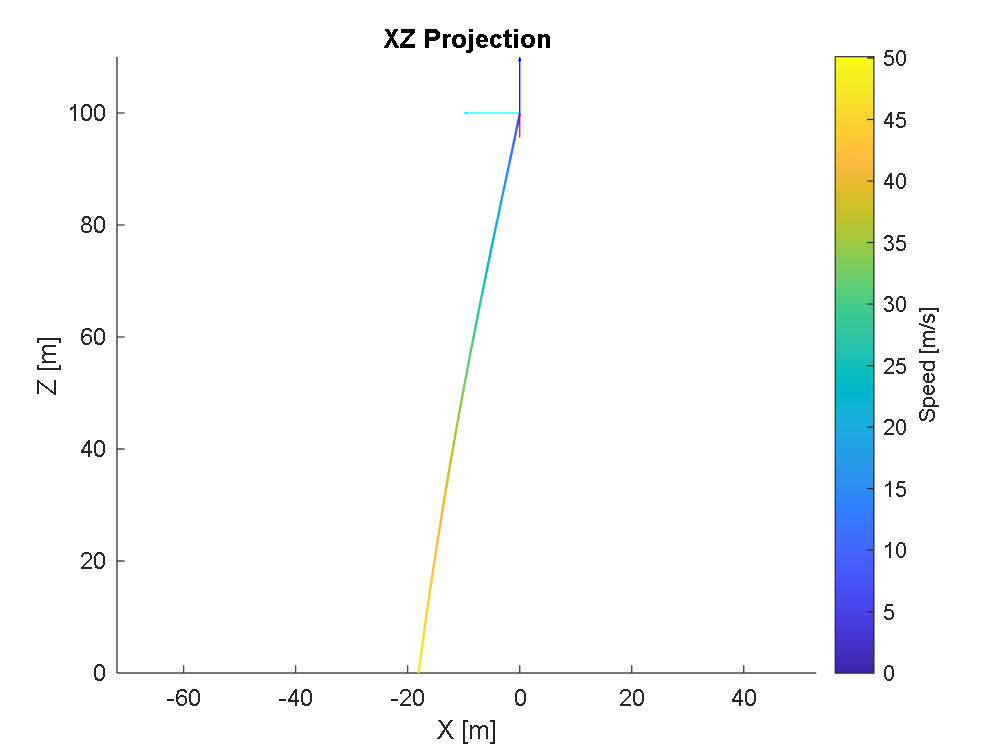

h = figure;

surface([simout.x(:, 1)';simout.x(:, 1)'], [simout.x(:, 3)';simout.x(:, 3)'], zeros(2, numel(simout.time)), [velocity';velocity'], 'FaceColor', 'no', 'EdgeColor', 'interp', 'LineWidth', 1);
c = colorbar;
c.Label.String = "Speed [m/s]";
xlim(x_lim)
ylim([0, z_max])
axis equal
xlabel("X [m]")
ylabel("Z [m]")
title("XZ Projection")


ax = gca;
ax.NextPlot = 'replaceChildren';

loops = numel(simout.time);
M(loops) = struct('cdata',[],'colormap',[]);

for j = 1:loops
    surface([simout.x(:, 1)';simout.x(:, 1)'], [simout.x(:, 3)';simout.x(:, 3)'], zeros(2, numel(simout.time)), [velocity';velocity'], 'FaceColor', 'no', 'EdgeColor', 'interp', 'LineWidth', 1); hold on
    quiver([simout.x(j, 1)], [simout.x(j, 3)], [b_x(1, 1, j)] .* z_max ./ 10, [b_x(3, 1, j)] .* z_max ./ 10, Color='b'); hold on
    quiver([simout.x(j, 1)], [simout.x(j, 3)], [b_y(1, 1, j)] .* z_max ./ 10, [b_y(3, 1, j)] .* z_max ./ 10, Color='g'); hold on
    quiver([simout.x(j, 1)], [simout.x(j, 3)], [b_z(1, 1, j)] .* z_max ./ 10, [b_z(3, 1, j)] .* z_max ./ 10, Color='cyan'); hold on
    plot([simout.x(j, 1), simout.x(j, 1) - squeeze(T_e(1, 1, j)) * z_max ./ 10], [simout.x(j, 3), simout.x(j, 3) - squeeze(T_e(3, 1, j)) * z_max ./ 10], Color = 'r'); hold off

    drawnow
    M(j) = getframe;

    fprintf("iter %g\n", j)
end

legend(["", "b_x", "b_y", "b_z", "Thrust"])

movie(M);

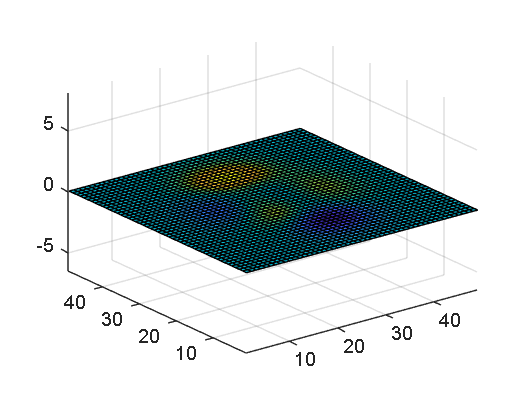

h = figure;
Z = peaks;
surf(Z)
axis tight manual


ax = gca;
ax.NextPlot = 'replaceChildren';

loops = 40;
M(loops) = struct('cdata',[],'colormap',[]);

for j = 1:loops
    X = sin(j*pi/10)*Z;
    surf(X,Z)
    drawnow
    M(j) = getframe;
end


movie(M);

p1 = Plots.plot(xc[1, :], xc[3, :], lc=:viridis, line_z=velocity, label = "", colorbar_title = "Speed")
Plots.quiver!([xc[1, i]], [xc[3, i]], quiver = ([b_x[1, i]], [b_x[3, i]]) .* z_max ./ 10, aspect_ratio=:equal, color = :blue, label = "b_x")
Plots.quiver!([xc[1, i]], [xc[3, i]], quiver = ([b_y[1, i]], [b_y[3, i]]) .* z_max ./ 10, aspect_ratio=:equal, color = :green, label = "b_y")
Plots.quiver!([xc[1, i]], [xc[3, i]], quiver = ([b_z[1, i]], [b_z[3, i]]) .* z_max ./ 10, aspect_ratio=:equal, color = :orange, label = "b_z")
Plots.plot!([xc[1, i], xc[1, i] - T_e[1, i] / T_max_ * z_max ./ 10], [xc[3, i], xc[3, i] - T_e[3, i] / T_max_ * z_max ./ 10], color = :red, label = "Thrust", axpect_ratio=:equal, ylim=(0, z_max), xlim=x_lim)
Plots.plot!(rectangle(z_max / 50,z_max / 20,xc[1, i],xc[3, i], [b_x[1, i]; b_x[3, i]]), label = "", opacity=.5, color = :gray)
Plots.plot!(LinRange(x_lim[1], x_lim[2], 100), abs.(LinRange(x_lim[1], x_lim[2], 100)) * tan(γ_gs_), linestyle = :dash, label = "", color = :gray, xticks=decimate_ticks(p1, :x))
Plots.title!("XZ Projection")
Plots.xlabel!("X [m]")
Plots.ylabel!("Z [m]")

p2 = Plots.plot(xc[2, :], xc[3, :], lc=:viridis, line_z=velocity, label = "", colorbar_title = "Speed")
Plots.quiver!([xc[2, i]], [xc[3, i]], quiver = ([b_x[2, i]], [b_x[3, i]]) .* z_max ./ 10, aspect_ratio=:equal, color = :blue, label = "b_x")
Plots.quiver!([xc[2, i]], [xc[3, i]], quiver = ([b_y[2, i]], [b_y[3, i]]) .* z_max ./ 10, aspect_ratio=:equal, color = :green, label = "b_y")
Plots.quiver!([xc[2, i]], [xc[3, i]], quiver = ([b_z[2, i]], [b_z[3, i]]) .* z_max ./ 10, aspect_ratio=:equal, color = :orange, label = "b_z")
Plots.plot!([xc[2, i], xc[2, i] - T_e[2, i] / T_max_ * z_max ./ 10], [xc[3, i], xc[3, i] - T_e[3, i] / T_max_ * z_max ./ 10], color = :red, label = "Thrust", axpect_ratio=:equal, ylim=(0, z_max), xlim=y_lim)
Plots.plot!(rectangle(z_max / 50,z_max / 20,xc[2, i],xc[3, i], [b_x[2, i]; b_x[3, i]]), label = "", opacity=.5, color = :gray)
Plots.plot!(LinRange(y_lim[1], y_lim[2], 100), abs.(LinRange(y_lim[1], y_lim[2], 100)) * tan(γ_gs_), linestyle = :dash, label = "", color = :gray, xticks=decimate_ticks(p2, :x))
Plots.title!("YZ Projection")
Plots.xlabel!("Y [m]")
Plots.ylabel!("Z [m]")